[https://jp.mathworks.com/help/deeplearning/ug/understand-network-predictions-using-lime.html](https://jp.mathworks.com/help/deeplearning/ug/understand-network-predictions-using-lime.html)

事前学習済みのネットワーク GoogLeNet を読み込みます。ｎload("Net_resnet_B10_E6_1e-3.mat");

% cd("C:\Users\Rhisamochi\Box\フェーズドアレイ超音波探傷\CRIEPI\入手データ\230411 電中研\MATLAB\ネットワーク");
% cd("C:\Users\Rhisamochi\Box\フェーズドアレイ超音波探傷\CRIEPI\入手データ\230411 電中研\MATLAB\ネットワーク");
% cd("C:\Users\Rhisamochi\Box\フェーズドアレイ超音波探傷\CRIEPI\入手データ\230411 電中研\MATLAB\ネットワーク");
% load("random_B10E40_1e-4_origin.mat",'net');
net = googlenet;

イメージの入力サイズとネットワークの出力クラスを抽出します。

inputSize = net.Layers(1).InputSize(1:2);
classes = net.Layers(end).Classes;

**イメージを読み込みます。(イメージは Sherlock という名前のレトリバーです。)イメージのサイズをネットワークの入力サイズに変更します。**

%cd("C:\Users\Rhisamochi\Box\フェーズドアレイ超音波探傷\CRIEPI\入手データ\0809 電中研\異なる柱状晶成長方向を有する試験体の底面画像\Linear_BScanCrop\中間濃度_jpg\BScanM00deg")
% cd("C:\Users\Rhisamochi\Box\フェーズドアレイ超音波探傷\CRIEPI\入手データ\230411 電中研\画像データ\3次元\元画像\⑤M00")
% cd("C:\Users\Rhisamochi\Box\フェーズドアレイ超音波探傷\CRIEPI\入手データ\230411 電中研\画像データ\LIME_mask\Net_alexnet_B10_E40_1e-5_3次元\true\①P15\")
%cd("C:\Users\Rhisamochi\Box\フェーズドアレイ超音波探傷\JAEA\20231129\image\垂直切り取り\分類用\欠陥あり")
cd("C:\Users\daikidaiku\Box\Personal\study\Data\2024\240311\Straight Line\分類用画像\3秒間隔\C")
img = imread("05_86.jpg");
%img = imread("image (42).png");

`Netに合わせてresize`

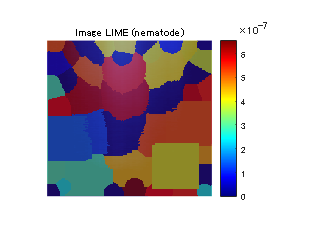

img = imresize(img,[224 224]);
% img = imresize(img,[227 227]);
imshow(img)

イメージを分類して、分類スコアの最も高い 3 つのクラスをイメージ タイトルに表示します。

[YPred,scores] = classify(net,img);
[~,topIdx] = maxk(scores, 3);
topScores = scores(topIdx);
topClasses = classes(topIdx);

imshow(img)

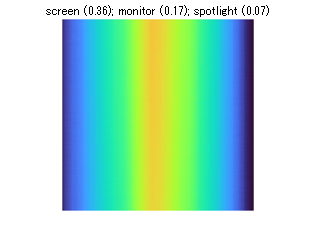

titleString = compose("%s (%.2f)",topClasses,topScores');
title(sprintf(join(titleString, "; ")));

**イメージ領域の特定**

LIME マップを重ね合わせた Sherlock のイメージを表示します。

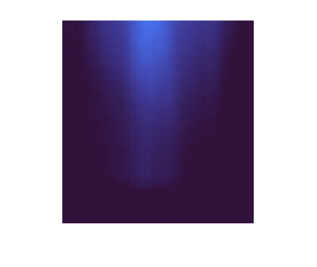

map = imageLIME(net,img,YPred);
figure
imshow(img,'InitialMagnification',150)
hold on
imagesc(map,'AlphaData',0.5)
colormap jet
colorbar

title(sprintf("Image LIME (%s)", ...
    YPred))
hold off

**異なるクラスの結果との比較**

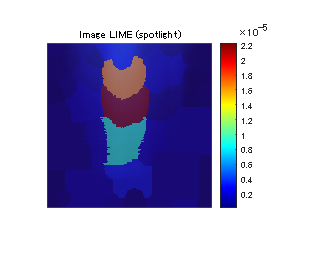

secondClass = topClasses(2);
map = imageLIME(net,img,secondClass);
figure;
imshow(img,'InitialMagnification',150)
hold on
imagesc(map,'AlphaData',0.5)
colormap jet
colorbar

title(sprintf("Image LIME (%s)",secondClass))
hold off

**LIME と Grad-CAM の比較**

map = imageLIME(net,img,"C", ...
    "Segmentation","grid",...
    "OutputUpsampling","bicubic",...
    "NumFeatures",100,...
    "NumSamples",6000,...
    "Model","linear");

次を使用中のエラー: imageLIME
クラス ラベルは、分類出力層のクラスと一致していなければなりません。


imshow(img,'InitialMagnification', 150)
hold on
imagesc(map,'AlphaData',0.5)
colormap jet

title(sprintf("Image LIME (%s - linear model)", ...
    YPred))
hold off

**最も重要な特徴のみの表示**

[map,featureMap,featureImportance] = imageLIME(net,img,YPred);

最も重要な 4 つの特徴のインデックスを見つけます。

numTopFeatures = 4;
[~,idx] = maxk(featureImportance,numTopFeatures);

mask = ismember(featureMap,idx);
maskedImg = uint8(mask).*img;

figure
imshow(maskedImg);
colormap(jet)

% hold on
% imagesc(colormap("jet"))
% hold off


title(sprintf("Image LIME (%s - top %i features)", ...
    YPred, numTopFeatures))